# The MathWorks Power Company

You are now an employee of the MathWorks power company, your mission is to design an hydropower plant to provide enough electricity to power all of MathWorks data center in its headquarter in Natick. The project would be to buil an aritificial mountain in the shape of MATLAB's membrane logo with a lake at its center. The lake collects water all year and this water is used to generate

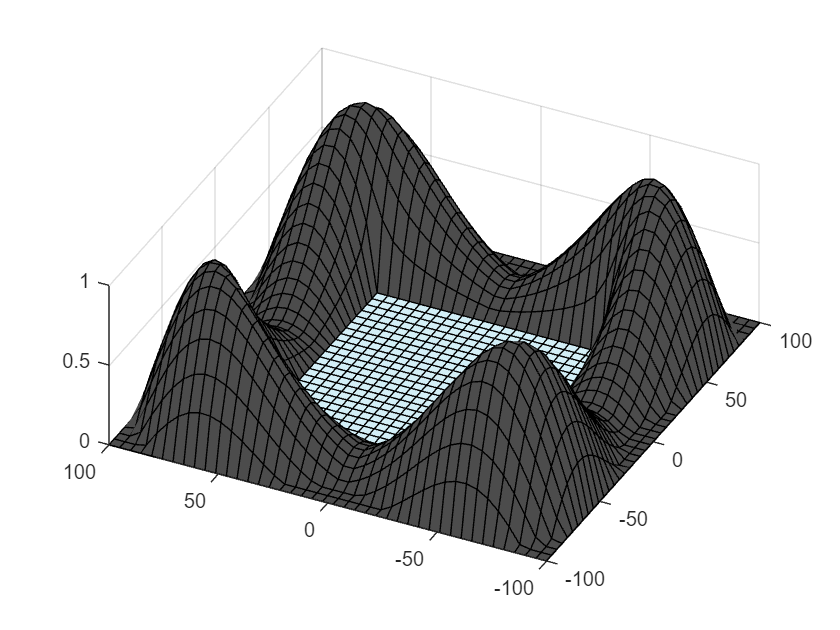

figure
Z = membrane(1,10);
Z = [[fliplr(Z) Z]; flipud([fliplr(Z) Z])];
n = size(Z,1);
[X,Y] = meshgrid(0:n-1,0:n-1);
X = 2*X/(n-1) - 1;
Y = 2*Y/(n-1) - 1;
C = zeros(size(Z));
C(11:31,11:31) = 1.0;
Z(1,:) = 0.0;
Z(end,:) = 0.0;
Z(:,1) = 0.0;
Z(1,end) = 0.0;
Z( Z < 0 ) = 0.0;
X = X * 100;
Y = Y * 100;
s = surf(X,Y,Z,C,"FaceColor","flat","EdgeColor","k");
view([-64 59])
mapFace = [0.3 0.3 0.3
           0.83 0.94 0.97];
colormap(mapFace)

1. model the turbine to get the power output based on the height of the lake, mass flow

2. model level of the lake with time with respect to time if it doenst rain

3. How much energy could be produced by the dam if the lake was emptied

4. Give rain data in the area to find how much energy can be produced to have a reliable source of power

5. 


$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$


$\rho S_\text{res}\frac{dh_\text{res}}{dt} = \dot{m}_\text{rain}-\dot{m}_\text{evap}-\dot{m}_\text{turbine}$model

## Model parameter

The lake section is a square of length L and it is 

L = 10000;
h = 200;
S = L^2;

## Mathematical model


$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\rho S_\text{res}\frac{dh_\text{res}}{dt} = \dot{m}_\text{rain}-\dot{m}_\text{evap}-\dot{m}_\text{turbine}$$


## Model the rainfall

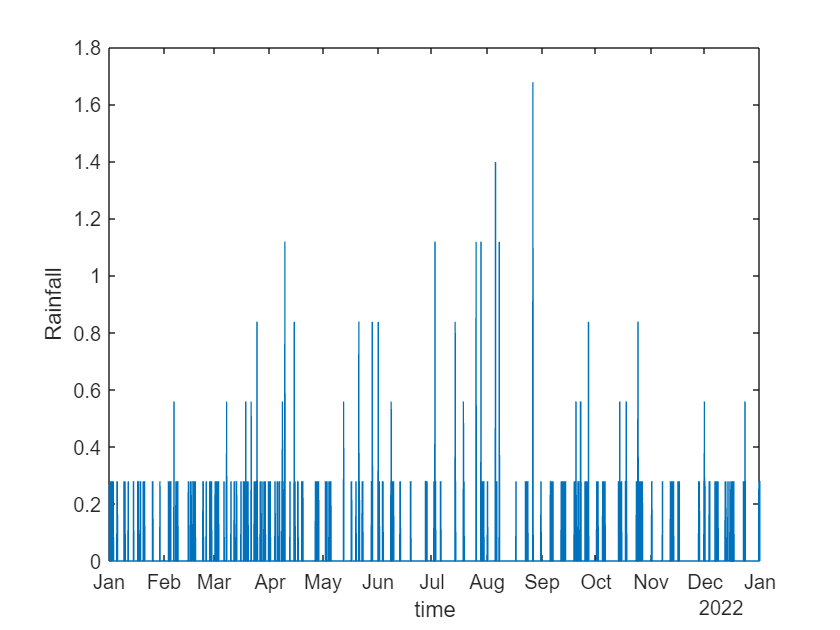

load NatickWeather.mat
figure
plot(weather,"time","Rainfall")

rain = trapz(weather.Rainfall);
Vrain = S*rain/1000

Vrain = 67922140

Model Evap

% Retime timetable
weather = retime(weather(:,[1 2 3 4 5 6]),"regular","mean",...
    "TimeStep",caldays(1));

% Retime each override variable to same time vector
TT = retime(weather(:,"Rainfall"),weather.Properties.RowTimes,"sum");
weather = addvars(weather,TT.(1),'Before',7,...
    'NewVariableNames',"Rainfall");
clear TT

% Display results
weather

newTimetable = 365×7 timetable
       time        T_w      T_a        Wind        RH       e_w       e_a      Rainfall
    ___________    ___    ________    _______    ______    ______    ______    ________
    01-Jan-2022     0       8.2611    0.44726    93.385    570.78    1023.7     1.9558 
    02-Jan-2022     0       5.5826     1.0795    91.463    559.03    844.01     3.6322 
    03-Jan-2022     0      -3.5184     2.6574    63.033    385.26    301.74     0.2794 
    04-Jan-2022     0      -4.2253     1.7413    49.112    300.18    219.28          0 
    05-Jan-2022     0       3.0132     1.8485    89.962    549.86    726.26     6.42


$$\dot{m}_\text{evap} = (a+bU)(e_w-e_a)$$


$U$ wind velocity in ms-1

$e_w-e_a$ vapour pressure deficit (mbar)


$$e_w = Psat( RH, T_w)$$



$$e_a = Psat(RH,T_a)$$


a = 0.17 (mm mbar-1 day-1)

b = 0.30 (mm mbar-1 m-1)

mm.day-1 = 0.001/86400* S m^3.s-1